## Digital Image Processing - COT 5930

## Research Project - Foveation Techniques for Medical Image Analysis

Dr. Scott Hammond

James Goedmakers

## Introduction

Foveated vision is a very common adaptation in the natural world, possibly for efficiency reasons. In this test we will evaluate the potential for foveated computer vision systems to potentially acheive the same efficiency benefits while preserving performance in visual tasks such as classification.

## Get the training images and classes

Create a datastore to the images.

imds = imageDatastore("SkinLesions");

Get the known classifications from a file and use these as the image labels.

groundtruth = readtable("SkinLesions.csv");
imds.Labels = categorical(groundtruth.Status);

View the first few images.

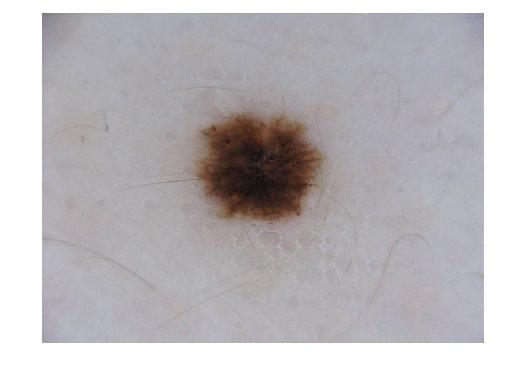

imshow(readimage(imds,2))

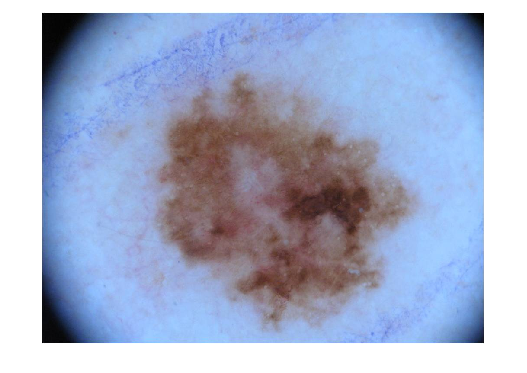

imshow(readimage(imds,3))

Divide data into training (60%) and testing (40%) sets

[trainImgs,testImgs] = splitEachLabel(imds,0.6,"randomized");

Create augmented image datastores to preprocess the images.

trainds = augmentedImageDatastore([224 224],trainImgs);
testds = augmentedImageDatastore([224 224],testImgs);

## Build a network

Start with a pretrained network

net = googlenet;
lgraph = layerGraph(net);

Take the CNN layer graph and replace the output layers.

newFc = fullyConnectedLayer(2,"Name","new_fc")

newFc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 2

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

     InputNames: {'data'}
    OutputNames: {'output'}
         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]


newOut = classificationLayer("Name","new_out")

newOut =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
    ClassWeights: 'none'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

     InputNames: {'data'}
    OutputNames: {'new_out'}
         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]


## Set some training options

options = trainingOptions("sgdm","InitialLearnRate", 0.001, ...
    "ExecutionEnvironment","gpu");

## Train the network

skinnet = trainNetwork(trainds,lgraph,options)

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       45.31% |       1.3813 |          0.0010 |
|      13 |          50 |       00:02:11 |       88.28% |       0.2991 |          0.0010 |
|      25 |         100 |       00:04:17 |       95.31% |       0.1076 |          0.0010 |
|      30 |         120 |       00:05:07 |      100.00% |       0.0513 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


skinnet =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


## Evaluate network on test data

Make predictions

preds = classify(skinnet,testds);

Compare with reality

truetest = testImgs.Labels;
nnz(preds == truetest)/numel(preds)

ans = 0.8361

View confusion matrix

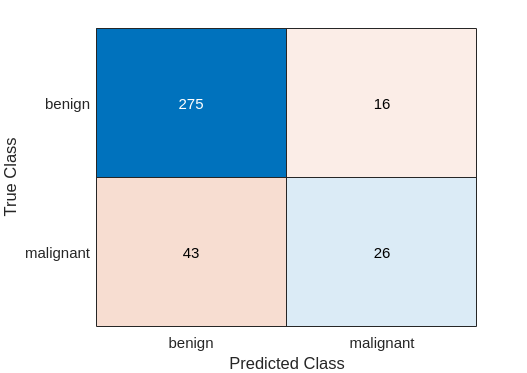

idx =      3
    12
    15
    21
    24
    25
    32
    48
    51
    52


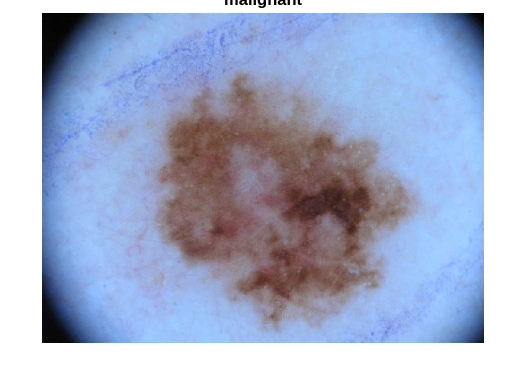

confusionchart(truetest,preds);

View first incorrect classification (if there is one)

idx = find(preds~=truetest)
if ~isempty(idx)
    imshow(readimage(testImgs,idx(1)))
    title(truetest(idx(1)))
end

## Compress/Foveate the Dataset

% This takes a long time to run
% Only run if foveated dataset not generated yet
filenames = dir("./SkinLesions/ISIC*.jpg");
num_files = length(dir("./SkinLesions/ISIC*.jpg"));

% for index = 1:num_files
%     image = imread("./SkinLesions/" + filenames(index).name);
%     foveated_image = foveate(image);
%     imwrite(foveated_image,"./SkinLesionsFoveated/" + filenames(index).name);
% end


## Compare the Original and Foveated

image = imread("./SkinLesions/ISIC_0000001.jpg");
image_foveated = imread("./SkinLesionsFoveated/ISIC_0000001.jpg");

imshow(image)

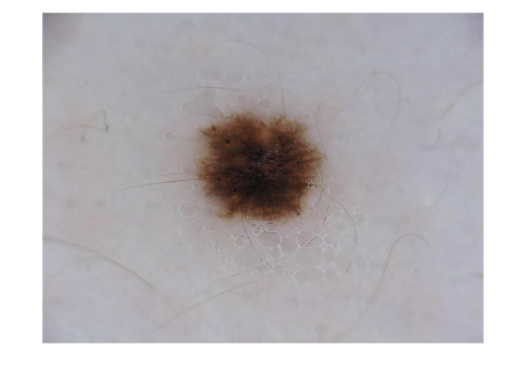

imshow(image_foveated)

## Get Foveated Images and Classes

Create a datastore to the images.

imds = imageDatastore("SkinLesionsFoveated");

Get the known classifications from a file and use these as the image labels.

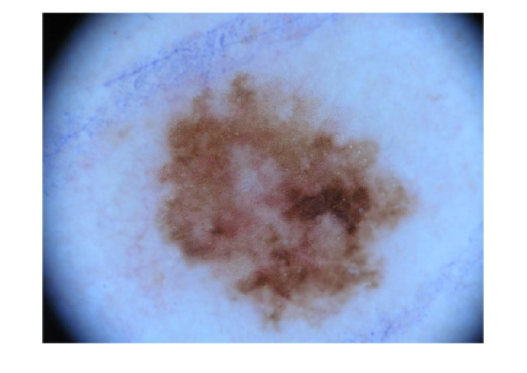

groundtruth = readtable("SkinLesions.csv");
imds.Labels = categorical(groundtruth.Status);

Divide data into training (60%) and testing (40%) sets

[trainImgs,testImgs] = splitEachLabel(imds,0.6,"randomized");

Create augmented image datastores to preprocess the images.

trainds = augmentedImageDatastore([224 224],trainImgs);
testds = augmentedImageDatastore([224 224],testImgs);

## Build a network

Start with a pretrained network

net = googlenet;
lgraph = layerGraph(net);

Take the CNN layer graph and replace the output layers.

newFc = fullyConnectedLayer(2,"Name","new_fc")

newFc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 2

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

     InputNames: {'data'}
    OutputNames: {'output'}
         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]


newOut = classificationLayer("Name","new_out")

newOut =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
    ClassWeights: 'none'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

     InputNames: {'data'}
    OutputNames: {'new_out'}
         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]


## Set some training options

options = trainingOptions("sgdm","InitialLearnRate", 0.001, ...
    "ExecutionEnvironment","gpu");

## Train the network

skinnet = trainNetwork(trainds,lgraph,options)

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       45.31% |       1.3596 |          0.0010 |
|      13 |          50 |       00:01:43 |       90.62% |       0.2559 |          0.0010 |
|      25 |         100 |       00:03:29 |       95.31% |       0.1255 |          0.0010 |
|      30 |         120 |       00:04:11 |       97.66% |       0.0854 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


skinnet =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


## Evaluate network on test data

Make predictions

preds = classify(skinnet,testds);

Compare with reality

truetest = testImgs.Labels;
nnz(preds == truetest)/numel(preds)

ans = 0.8139

View confusion matrix

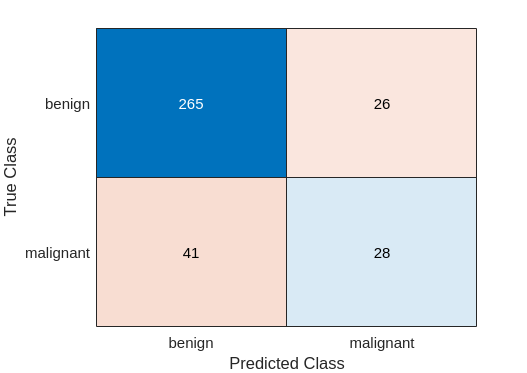

idx =      1
    10
    14
    20
    25
    27
    36
    39
    40
    41


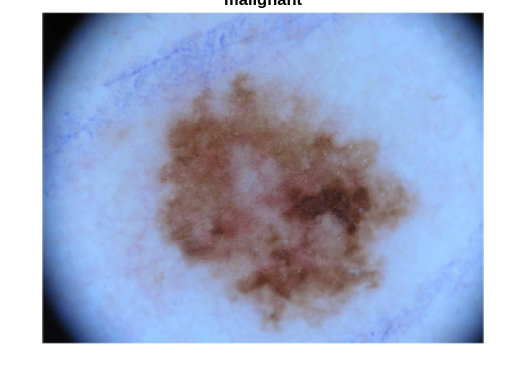

confusionchart(truetest,preds);

## Foveate Function Definition

function foveated_image = foveate(image)
    
    % Parameters for foveation
    fovea_size = 500; % Size of the foveated region
    % Preserve the fovea image quality
    fovea_resolution = 1; % Resolution scale factor for the foveated region
    % Setting higher than 1 led to some array multiplication errors
    % Compress the peripheral image quality
    peripheral_resolution = 0.5; % Resolution scale factor for the peripheral region
    
    % Create a grid of coordinates for the image
    [x, y] = meshgrid(1:size(image, 2), 1:size(image, 1));
    
    % Calculate the distance from each pixel to the center
    center_x = size(image, 2) / 2;
    center_y = size(image, 1) / 2;
    distance = sqrt((x - center_x).^2 + (y - center_y).^2);
    
    % Define masks for foveated and peripheral regions
    fovea_mask = distance <= fovea_size / 2;
    peripheral_mask = ~fovea_mask;
    
    % Create a blurred version of the peripheral region
    blurred_peripheral = imgaussfilt(image, 2);
    
    % Resize the foveated region to higher resolution
    foveated_region = imresize(image, fovea_resolution);
    
    % Combine the foveated and peripheral regions
    foveated_image = uint8(double(foveated_region) .* double(fovea_mask)) + uint8(double(blurred_peripheral) .* double(peripheral_mask));
end


## Conclusions

The results are promising, as the foveated imagery is only about 2% lower in classification accuracy compared to the originals. Although overall classification accuracy being below 90% makes either method unsuitable for high risk tasks such as skin cancer classification, additional testing or applications may provide scenarios in which visual task performance can be increased, or required minimum accuracy levels can be lowered.